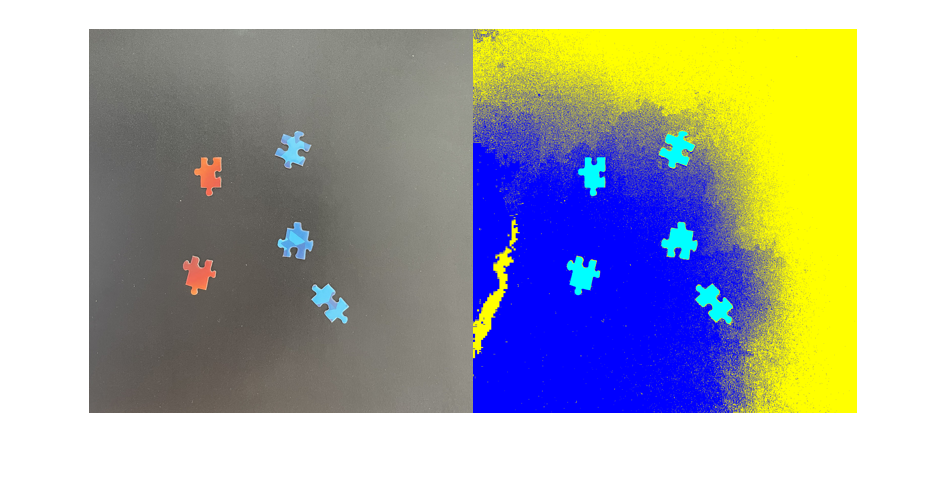

img = imread("Puzzle_06.jpg");

HSV = rgb2hsv(img);

K = 3;

labels = imsegkmeans(im2single(HSV),K);

montage({img,label2rgb(labels)})

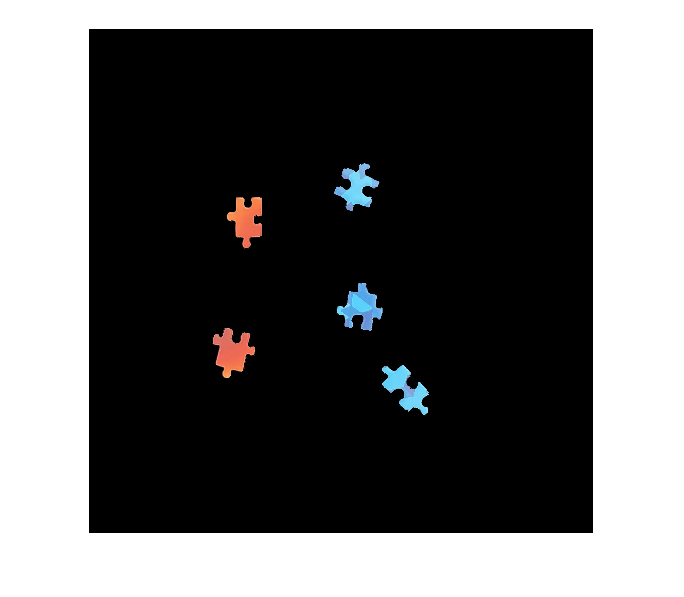


chipmask = HSV(:,:,2) > 0.35;

HSVchip = HSV;


HSVchip(~repmat(chipmask,1,1,3)) = 0;

BW = hsv2rgb(HSVchip);

imshow(BW);

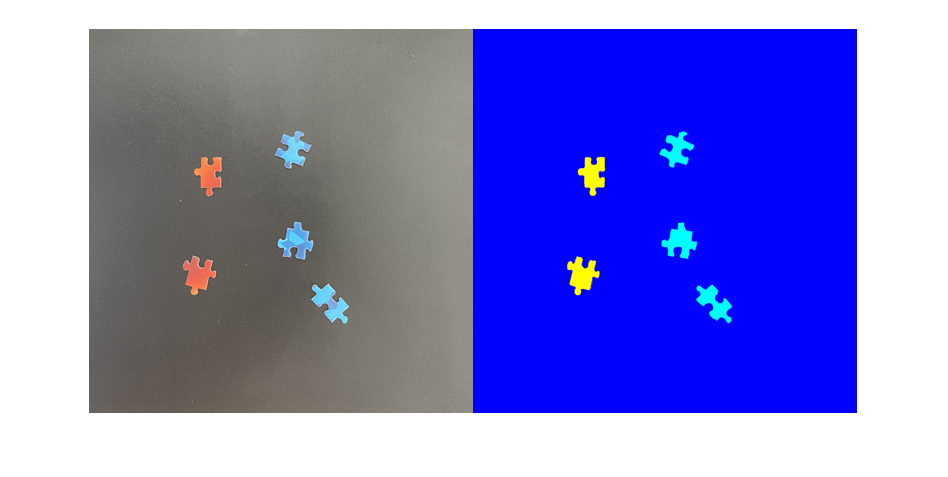


K = 3;

labels = imsegkmeans(im2single(HSVchip),K);

montage({img,label2rgb(labels)})